# **09 - Filtry s nekonečnou impulzní odezvou (IIR)**

Filtry představují lineární časově invariantní (LTI) systém, který přenáší/tlumí požadované frekvenční pásmo. Inverzním Fourierovým obrazem přenosové funkce filtru je jeho impulzní odezva, která je oproti FIR u **IIR** **nekonečná**.  To je způsobeno **zpětnovazebními zpožďovacími členy**, které vracejí výstup systému zpět do sčítačky. IIR mohou být čistě zpětnovazebné nebo obsahovat i dopřednou FIR část.  

**Řád filtru u IIR** reprezentuje počet zpožďovacích členů v mřížkové struktuře filtru **ve zpětné vazbě**, tj. řád filtru *N* koresponduje s počtem komplexních pólů. Konvoluce nelze pro infinitní impulzní odezvu realizovat jako u FIR konvolucí signálu a finitní masky. Proto je výpočet u IIR realizován rekurzivně:    

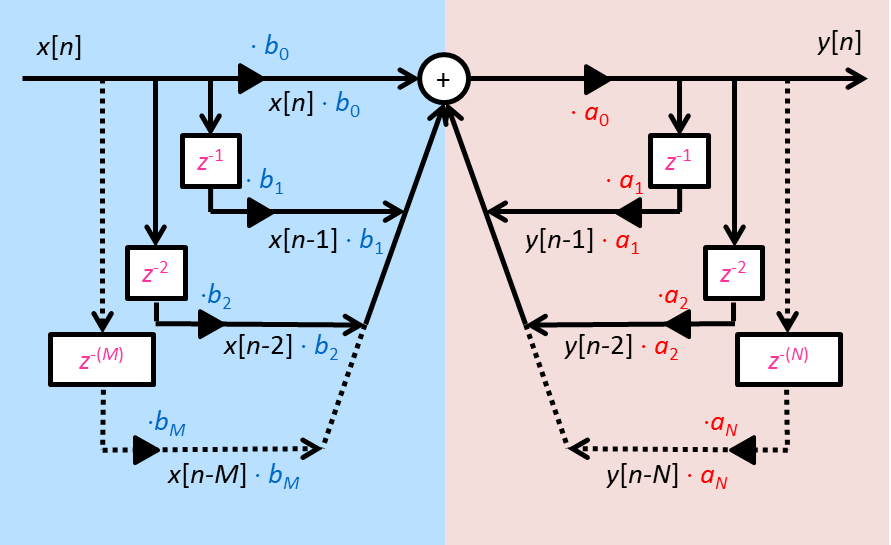

Mřížková struktura přepsána do diferenční rovnice (rekurzivní výpočet):

  
$$a_0 y{\left[n\right]}+a_1 y{\left[n-1\right]}+\ldots+a_N y{\left[n-N\right]}=b_0 x{\left[n\right]}+b_1 x{\left[n-1\right]}+\ldots+b_M x{\left[n-M\right]}$$


Z věty o posunu v čase ve Fourierově transformaci vychází tzv. **Z-transformace** ($z^{-M} =\ e^{i\omega M}$), která přepisuje diferenční rovnici v čase do komplexní (frekvenční) z-roviny, tj. superpozici spekter jednotlivých harmonických složek, $y\left\lbrack n\right\rbrack \longrightarrow Y\left\lbrack z\right\rbrack$, ..., $y\left\lbrack n-M\right\rbrack \longrightarrow Y\left\lbrack z\right\rbrack \cdot z^{-M}$ :

 
$$\begin{array}{l}
a_0 y{\left[n\right]}+a_1 y{\left[n-1\right]}+\ldots+a_N y{\left[n-N\right]}=b_0 x{\left[n\right]}+b_1 x{\left[n-1\right]}+\ldots+b_M x{\left[n-M\right]}\\
a_0 y{\left[n\right]}=b_0 x{\left[n\right]}+b_1 x{\left[n-1\right]}+\ldots+b_M x{\left[n-M\right]}-a_1 y{\left[n-1\right]}-\ldots-a_N y{\left[n-N\right]}\\
a_0 Y{\left[z\right]}=b_0 X{\left[z\right]}+b_1 z^{-1} X{\left[z\right]}+\ldots+b_M z^{-M} X{\left[z\right]}-a_1 z^{-1} Y{\left[z\right]}-\ldots-a_N z^{-N} Y{\left[z\right]}
\end{array}$$


Vyjádřením přenosové funkce  $H\left\lbrack z\right\rbrack =\frac{Y\left\lbrack z\right\rbrack }{X\left\lbrack z\right\rbrack }$ dostáváme polynom:

 
$$H{\left[z\right]}=\frac{Y\left\lbrack z\right\rbrack }{X\left\lbrack z\right\rbrack }=\frac{1}{\textrm{𝑋}\left\lbrack \textrm{𝑧}\right\rbrack }\cdot \frac{\textrm{𝑋}\left\lbrack \textrm{𝑧}\right\rbrack \left({\textrm{𝑏}}_0 +b_1 z^{-1} +\ldots+{\textrm{𝑏}}_M z^{-M} \right)}{\left(a_0 +a_1 z^{-1} +\ldots+a_N z^{-N} \right)}=\frac{\sum_{m=0}^M b_m z^{-m} }{\sum_{k=0}^N a_k z^{-k} }$$


Vyřešením kořenů polynomu získáváme tzv. póly a nuly, ve kterých hodnoty z-roviny nabývají extrémních hodnot (nuly: 0, póly: $\infty$). Na rozdíl od FIR (všechny póly jsou v nule), u IIR póly mohou ležet kdekoli i mimo jednotkovou kružnici komplexní z-roviny. Pro** stabilitu filtru** (nesmí akumulovat energii) musí vždy ležet **uvnitř jednotkové kružnice!**  Inverzní z-transformací (substitucí $z^{-M} =\ e^{-i\omega M}$) vzniká komplexní z-rovina celého oboru komplexních čísel  a po dosazení do polynomu přenosové funkce tzv. membránový model z-roviny ($H\left\lbrack z\right\rbrack ,\;\textrm{kde}\;z\in C$). Membrána z-roviny je deformována pozicí nul a pólů. Přenos filtru je pak popsán hodnotami ležícími právě na jednotkové kružnici $\left|H\left\lbrack 1e^{j\omega } \right\rbrack \right|$. Impulzní odezva IIR filtru není symetrická ani antisymetrická, proto **fázové zpoždění není lineární**.

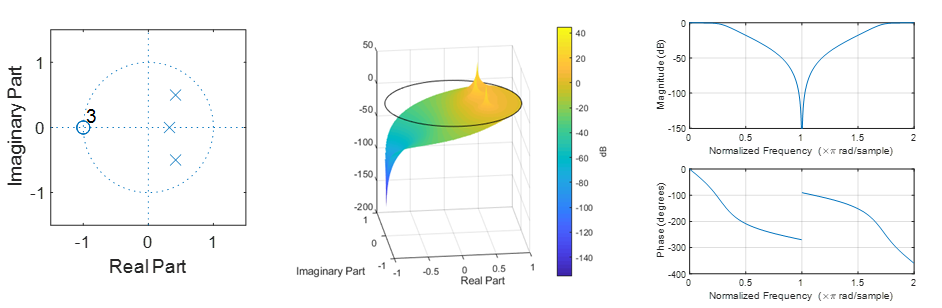Př.: Butterworthova filtru 3. řádu

Základní typy IIR filtrů (DP, HP, PP, PZ) lze realizovat pomocí známých polynomiálních funkcí, jejichž rozložení pólů a nul je známo (Butterworthovy, Chebyshevovy, eliptické Cauerovy polynomy). V případě návrhu jednoduchých filtrů jako je integrátor (sumátor), rezonátor nebo notch-filtr stačí znát rozložené pólů a nul, zpětným výpočtem můžeme určit koeficienty polynomu. I u IIR filtrů můžeme použít návrhových nástrojů, které hledají vhodnou přenosovou funkci uvnitř tolerančního pole přenosové charakteristiky (`filterDesigner`).

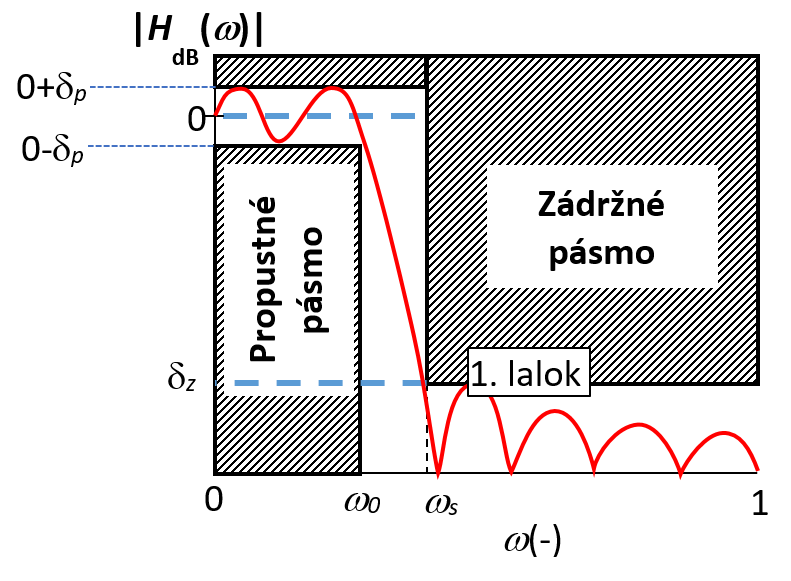

Zásadním rozdílem IIR oproti FIR je přítomnost zpětných vazeb, které výrazně **zvyšují strmost filtrů**. Proto lze dosáhnout strmých charakteristik i při nízkých řádech filtru (jednotky). Cenou za to ovšem je silně **nelineární fázová charakteristika** (zpoždění filtru), **riziko nestability** (póly musí být uvnitř jednotkové kružnice). Koeficienty $a_k$ IIR polynomu musí být **číselně velmi přesné**, při použití datového typu nižší bitové hloubky (integer vs. double) dochází k zaokrouhlování a k výrazné deformaci přenosové charakteristiky. U výpočetních systémů s omezenou datovou přesností (např. 8/16 bit) mohou být koeficienty kvantovány mimo jednotkovou kružnici a filtr se stává nestabilním!** Při návrhu IIR filtrů je vždy bezpodmínečně nutná kontrola polohy pólů uvnitř jednotkové kružnice a kontrola výsledné přenosové funkce!** Jakákoliv numerická nestabilita se projeví rozkmitáním, nespojitostmi apod.

**Nelineární fázové zpoždění** filtrů lze kompenzovat pomocí techniky dvojité filtrace **zero-phase filtering**. Algoritmus spočívá v standardní filtraci signálu$u\left\lbrack n\right\rbrack =h\left(x\left\lbrack n\right\rbrack \right)$, ve spektru pak $U\left\lbrack f\right\rbrack =X\left\lbrack f\right\rbrack \cdot H\left\lbrack f\right\rbrack$, kde $H\left\lbrack f\right\rbrack$ je přenos filtru. Výstup je invertován v čase $u\left\lbrack -n\right\rbrack$, což se ve spektru projeví komplexním sdružením $U{\left\lbrack f\right\rbrack }^* =X{\left\lbrack f\right\rbrack }^* \cdot H{\left\lbrack f\right\rbrack }^*$ (změna znamínka fázového spektra). Invertovaný signál je znovu filtrován $y\left\lbrack -n\right\rbrack =h\left(u\left\lbrack -n\right\rbrack \right)$, tj. ve spektru $Y{\left\lbrack f\right\rbrack }^* =X{\left\lbrack f\right\rbrack }^* \cdot H{\left\lbrack f\right\rbrack }^* \cdot H\left\lbrack f\right\rbrack =X{\left\lbrack f\right\rbrack }^* \cdot {\left|H\left\lbrack f\right\rbrack \right|}^2$. Nakonec je výstup druhé filtrace zpět invertován v čase, čímž získáme filtrovaný signál s nulovým fázovým posunem $y\left\lbrack n\right\rbrack$, ve spektru $Y\left\lbrack f\right\rbrack =X\left\lbrack f\right\rbrack {\cdot \left|H\left\lbrack f\right\rbrack \right|}^2$. Útlum dvojité filtrace tedy bude dvojnásobný (v dB).

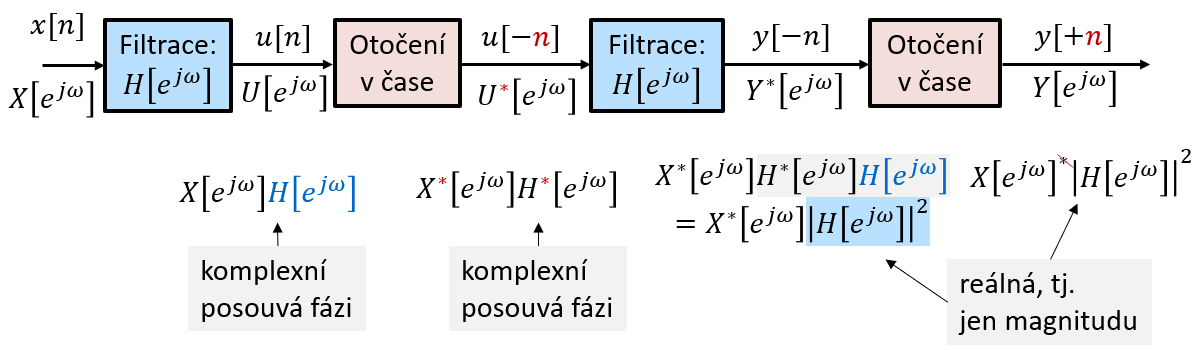

Zero-phase filtering je realizována funkcí `filtfilt.`

**Cíle:**

**Základní filtrace biologického signálu (např. intrakraniální EEG):**

    **1) Odstranění izolinie (pomalých složek signál): **

- **Realizujte strmou horní propust HP:**

- **Zlomový kmitočet **$f_{\textrm{HP}} =0\ldotp 5\;\textrm{Hz}$

- **Typ filtru (např. eliptický)**

**    2) Omezení pásma a vysokofrekvenčního rušení: **

- **Navrhněte doplní propust DP:**

- **Zlomový kmitočet **$f_{\textrm{DP}} =600\;\textrm{Hz}$

- **Typ filtru (např. Butterworth)**

**    3) Úzkopásmová filtrace násobků 50 Hz: **

- **Navrhněte kaskádu notch-filtrů síťového rušení** 

- **Zlomový kmitočet **$f_{\textrm{PZ}} =k\times 50\;\textrm{Hz}$

- **Typ filtru (bikvadratický)**

**    4) Pásmová filtrace - výběr pásma: **

- **Navrhněte pásmovou propust **

- **Gama pásmo EEG 25-100 Hz**

- **Typ filtru (např. inverzní Chebyshev Typ II)**

**    5) Využívejte filtrce bez posunu fáze: **

- `filtfilt`

- `Vykreslete odhad PSD filtrovaných signálů`

**Užitečné funkce: **`zplane, freqz, pwelch, filtfilt, buttord, butter, cheb2ord, cheby2, ellipord, ellip, sound`

**Užitečné nástroje:**` filterDesigner`

## `Nápověda:`

clear all; close all; clc

### Návrh IIR filtrů

Vyzkoušejte si návrh různých typů IIR filtrů (HP, DP, notch a PP). Zobrazte si rozložení pólů a nul, zobrazte včetně frekvenční charakteristiky.

**Načtěte si signál intrakraniálního EEG**

% obsahuje "eeg" a "fs"=2048 Hz
load('ieeg_seizure.mat');

**1) Horní propust**

Při snímání elektrofyziologických signálů (EKG, EEG aj.) dochází na rozhraní elektrody a tkáně (rozhraní kov-elektrolit) ke vzniku půlčlánkového potenciálu, který se mění vlivem vysychání elektrolytu, pohybu elektrody či teploty. To se v signálu projeví pomalými změnami v signálu, tzv. signál plave (kolísání izolinie). Proto je potřeba tyto nízkofrekvenční složky ($f_0$<1 Hz) ze signálu filtrovat. Vzhledem k obecně mnohem vyšším vzorkovacím kmitočtům se jedná o filtraci velmi úzkého pásma, proto i navržená horní propust musí být ostrá. Můžeme tedy využít eliptických filtů, které jsou z rodiny IIR propustí nesjtrmější.

Dle požadavků tolerančního pásma odhadněte řád filtru a jeho koeficienty.

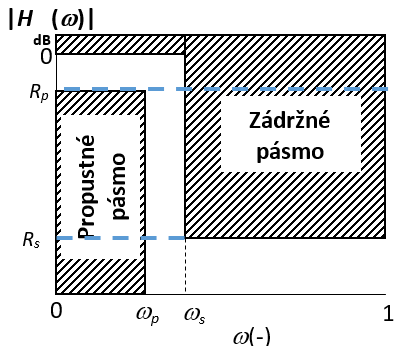 Pozn.: normovaný kmitočet $\omega_0 =\frac{\;f_{0\;} }{\frac{f_s }{2}}=2\frac{f_0 }{f_s }$

Wp = 2*0.5/fs;        % Wp=... zlomový normovaný kmitočet odpovídající fp=0.5 Hz
Rp=0.1; %        max. zvlnění v propustném 0.1 dB
Rs=60;  %        útlum 60 dB na kmitočtu Ws
Ws = 2*0.1/fs;        % Ws=... normovaný kmitočet při požadovaném útlumu = 0.1 Hz ~ Rs=60 dB

[ne,Wp]=ellipord(Wp,Ws,Rp,Rs); % řád filtru
[bhp,ahp]=ellip(ne,Rp,Rs,Wp,'high');

Pozn.: toleranční pole se definuje pro DP prototyp 

**Zobrazte rozložení pólů a nul, zkontrolujte stabilitu filtru a zobrazte modul přenosové charakteristiky filtru v dB (detail 0-3 Hz):**

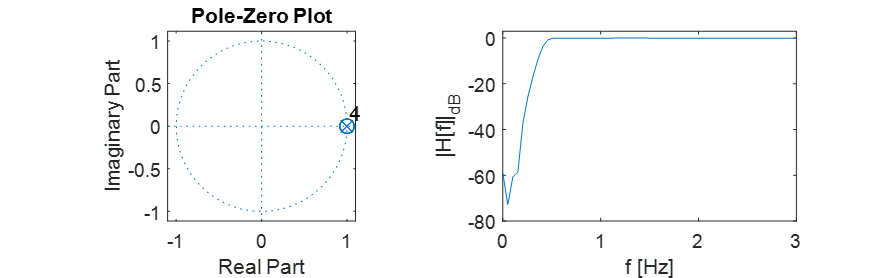

Pozn.: frekvenční charakteristiku vykreslete **s velkým rozlišením**, např. pro ${10}^5$ bodů, jinak nemusí být strmá část dobře vykreslená.

[H, f] = freqz(bhp,ahp,100*fs,fs);
roots(ahp)

ans =    0.9997 + 0.0013i
   0.9997 - 0.0013i
   0.9985 + 0.0011i
   0.9985 - 0.0011i


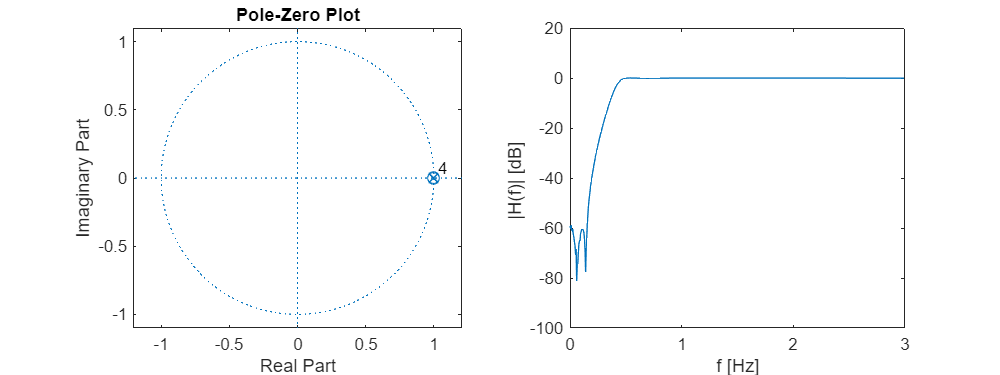

figure 
set(gcf,'Position', [0 0 800 300])
subplot(121)
zplane(bhp,ahp)
subplot(122)
plot(f(f<3),real(20*log10(H(f<3))))
ylabel('|H(f)| [dB] ')
xlabel('f [Hz]')

**Leží póly mimo jednotkovou kružnici? ne **

**Jaký je řád filtru?** 4

**Je filtr stabilní? ano**

**2) Dolní propust**

Pro eliminaci vysokofrekvenčního rušení odstraníme frekvenční pásmo, které nás ve vztahu k hodnocenému signálu nezajímají, tj. >600 Hz pro intrakraniální EEG. Navrhněte dolní propust typu Butterworth.

Wp = 2*600/fs        % Wp=... normovaný zlomový kmitočet 600 Hz

Wp = 0.5859

Rp=0.1; %        max. zvlnění v propustném 0.1 dB
Rs=60;  %        útlum 60 dB na kmitočtu Ws
Ws = 2*750/fs        % Ws=... normovaný kmitočet při požadovaném útlumu 750 Hz 

Ws = 0.7324


[nb,Wn]=buttord(Wp,Ws,Rp,Rs); % řád filtru
[bdp,adp]=butter(nb,Wn);
[H, f] = freqz(bdp,adp,100*fs,fs);

 **Zobrazte rozložení pólů a nul, zkontrolujte stabilitu filtru a zobrazte modul přenosové charakteristiky filtru v dB:**

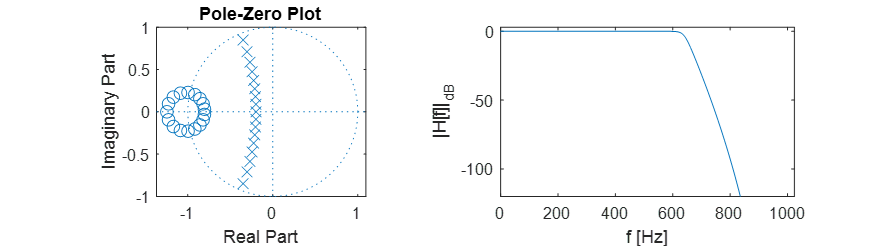

Pozn.: frekvenční charakteristiku vykreslete s velkým rozlišením, např. pro ${10}^5$ bodů

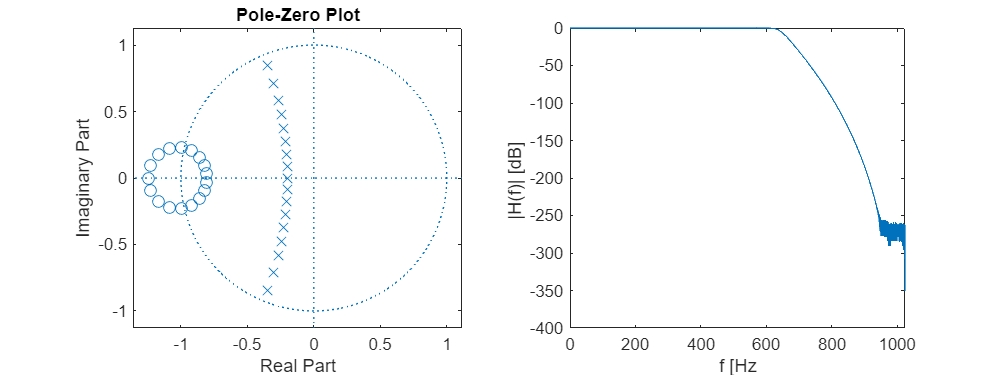

figure
set(gcf,'Position', [0 0 800 300])
subplot(121);
zplane(bdp, adp);
subplot(122)
plot(f, real(20*log10(H)))
ylabel('|H(f)| [dB] ')
xlabel('f [Hz')

**Leží póly vně jednotkové kružnice?** ne

**Jaký je řád filtru?  17**

**Je filtr stabilní?**  ano

**3) Pásmová zádrž - bikvadratický notch filtr n×50 Hz**

Navrhněte filtr, jehož póly a nuly leží v z-rovině pod úhlem $\omega_0 =2\cdot \frac{f_0 }{f_s }$. Šířku pásma můžete měnit vzdáloností pólů a nul od sebe. Póly leží uvnitř jednotkové kružnice ve vzdáleností od středu $r$ (poloměr menší kružnice), nuly leží na jednotkové kružnici, tedy poloměr $R=1$. Čím blíže budou póly nulám na jednotkové kružnici, tím bude pásmo (zářez) notch-filtru užší. Název bikvadratický filtr vychází z předpisu diferenční rovnice $H\left\lbrack z\right\rbrack =\frac{b_0 {\cdot z}^2 +b_1 {\cdot z}^2 +b_2 }{a_0 {\cdot z}^2 +a_1 {\cdot z}^2 +a_2 }$, kde v čitateli i jmenovateli máme kvadratické funkce. Hodnoty koeficientů filtru $\mathbf{b}$ a $\mathbf{a}$ nebudeme složitě odvozovat a spokojíme se již s řešením:


$$\mathbf{b}:\;b_0 =1;\;\;\;\;\;b_1 =-2\cdot R\cdot \cos \left(\pi \omega_0 \right);\;\;\;\;\;b_2 =R^2$$


 
$$\mathbf{a}:\;a_0 =1;\;\;\;\;\;a_1 =-2\cdot r\cdot \cos \left(\pi \omega_0 \right);\;\;\;\;\;\;a_2 =r^2$$
 

V MATLAB můžeme využít funkce, která umí póly a nuly v z-rovině přepočítat na koeficienty polynomu `zp2tf`:


$$\begin{array}{l}
\textrm{nuly}:\left\lbrack R\cdot e^{+i\pi \omega_0 } ,R\cdot e^{-i\pi \omega_0 } \right\rbrack \\
\textrm{póly}:\left\lbrack r\cdot e^{+i\pi \omega_0 } ,r\cdot e^{-i\pi \omega_0 } \right\rbrack 
\end{array}$$


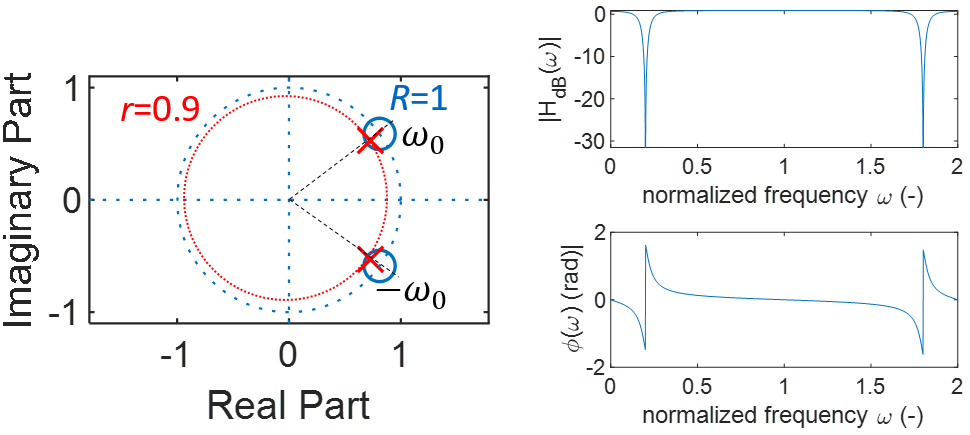

**Nyní realizujte filtr pro **$f_0 =50\;\textrm{Hz}$**, zobrazte rozložení pólů a nul včetně přenosové charakteristiky. Pozn.: předpis funkce realizujte přes proměnou **`f0`**, abyste mohli generovat koeficienty [**`b,a]`** i pro jiné frekvence. Poloměry volte *****R*****=1, *****r*****=0.9.**

 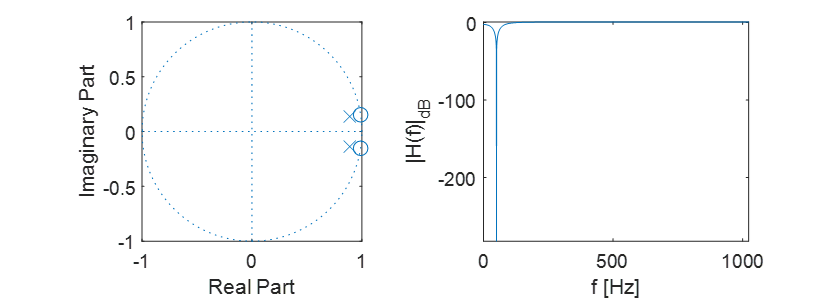

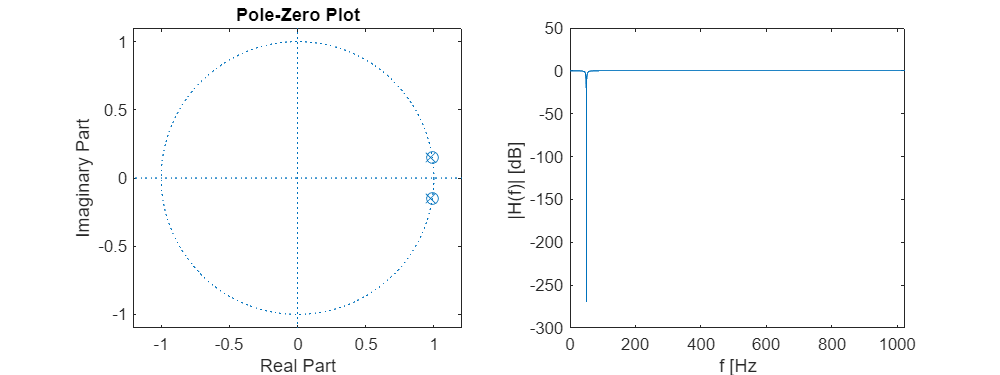

R = 1;
r = 0.99;
f0 = 50;
w0 = 2*f0/fs;
[b50, a50] = zp2tf([R*exp(1i*pi*w0);R*exp(-1i*pi*w0)], [r*exp(1i*pi*w0);r*exp(-1i*pi*w0)],1);        % [b50,a50]=zp2tf(...); % doplňte
[H, f] = freqz(b50,a50,100*fs,fs);
H_db = real(20*log10(H));
figure
set(gcf,'Position', [0 0 800 300])
subplot(121);
zplane(b50, a50);
subplot(122)
plot(f, real(20*log10(H)))
ylabel('|H(f)| [dB] ')
xlabel('f [Hz')

        % freqz(...) % stačí modul
f_edges = f(H_db< -3);
f_edges = f_edges([1 end]);
notch_width = f_edges(end) -f_edges(1)

notch_width = 6.4400

Podívejte se, jaký efekt má poloměr `r` na šířku notch pásma.

**Jaká je šířka pásma notch filtru pro **`r=0.9`**?  66.16 Hz **(Pozn. mezi frekvencemi s útlumem -3 dB, interval "od-do" Hz)

**Jaká je šířka pásma notch filtru pro **`r=0.99`**? 6.4**(Pozn. mezi frekvencemi s útlumem -3 dB, interval "od-do" Hz) 

**4) Pásmová propust - výběr gama paásma 25 až 100 Hz**

V mnoha případech je začátek epileptického záchvatu doprovázen zvýšením rychlé aktivity v pásmu gama zapříčiněné pravděpodobně aktivací interneuronů. Navrhněte pásmovou propust Chebyshevova filtru typu 2 v pásmu 25 až 100 Hz. Odhad řádu `cheby2ord `je pro prototyp dolní propusti, proto představa převodu na pásmovou propust nemusí být intuitivní. Ve většině případů nám stačí volit řád filtru citem a kontrolovat přenosovou funkci. Při přesných požadavcích tolerančního pásma je lépe složit pásmovou propust (PP) kombinací horní a dolní propusti (HP+DP). Jednoduchý návrh PP bez přesných požadavků můžeme realizovat např. řádem 5, požadovaný útlum 60 dB:

nch=5;  % zvolený řád filtru
Rs=60;  % útlum v zádržném pásmu (dB)
Wp = [2*25/fs 2*100/fs];        % Wp=... mezní normovaný kmitočet propustného pásma [Wp1 Wp2]
Ws = [2*10/fs 2*115/fs];        % Ws=... mezní normovaný kmitočet zádržného pásma [Ws1 Ws2]
[n_dopocet, Wn] = cheb2ord(Wp,Ws,Rp,Rs);
 [bpp ,app] = cheby2(nch,Rs,Wn,'bandpass');       % [bpp,app]=cheby2(...,'bandpass'); % doplňte
 [H, f] = freqz(bpp,app,100*fs,fs)

H =   -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


f = 1.0e+03 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


** Zobrazte rozložení pólů a nul včetně přenosové charakteristiky.**

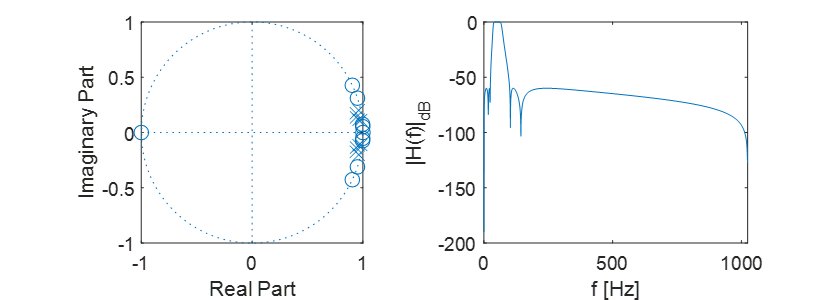

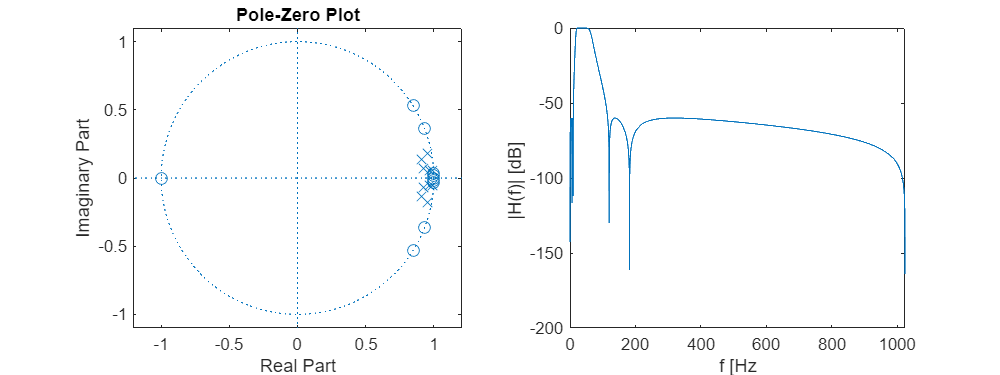

figure
set(gcf,'Position', [0 0 800 300])
subplot(121);
zplane(bpp, app);
subplot(122)
plot(f, real(20*log10(H)))
ylabel('|H(f)| [dB] ')
xlabel('f [Hz')

**5) Filtrace signálu kaskádou filtrů**

Jak název napovídá, v lineárně časově invariantních soustavách (LTI) platí linearita a princip superpozice. Postupná filtrace signálu může tedy probíhat v libovolném pořadí řazení jednotlivých filtrů. Zde však budeme respektovat řazení dle zadání:

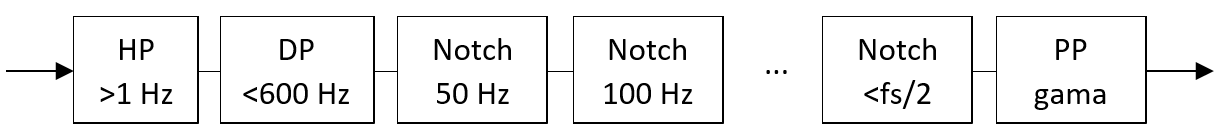 

**Postupně filtrujte signál** filtrem bez posunu fáze (`filtfilt`) kaskádou filtů. Vykreslete odhad PSD Welchovou metodou (`pwelch`):

- RAW signál

- filtrace horní propustí

- filtrace dolní propustí 

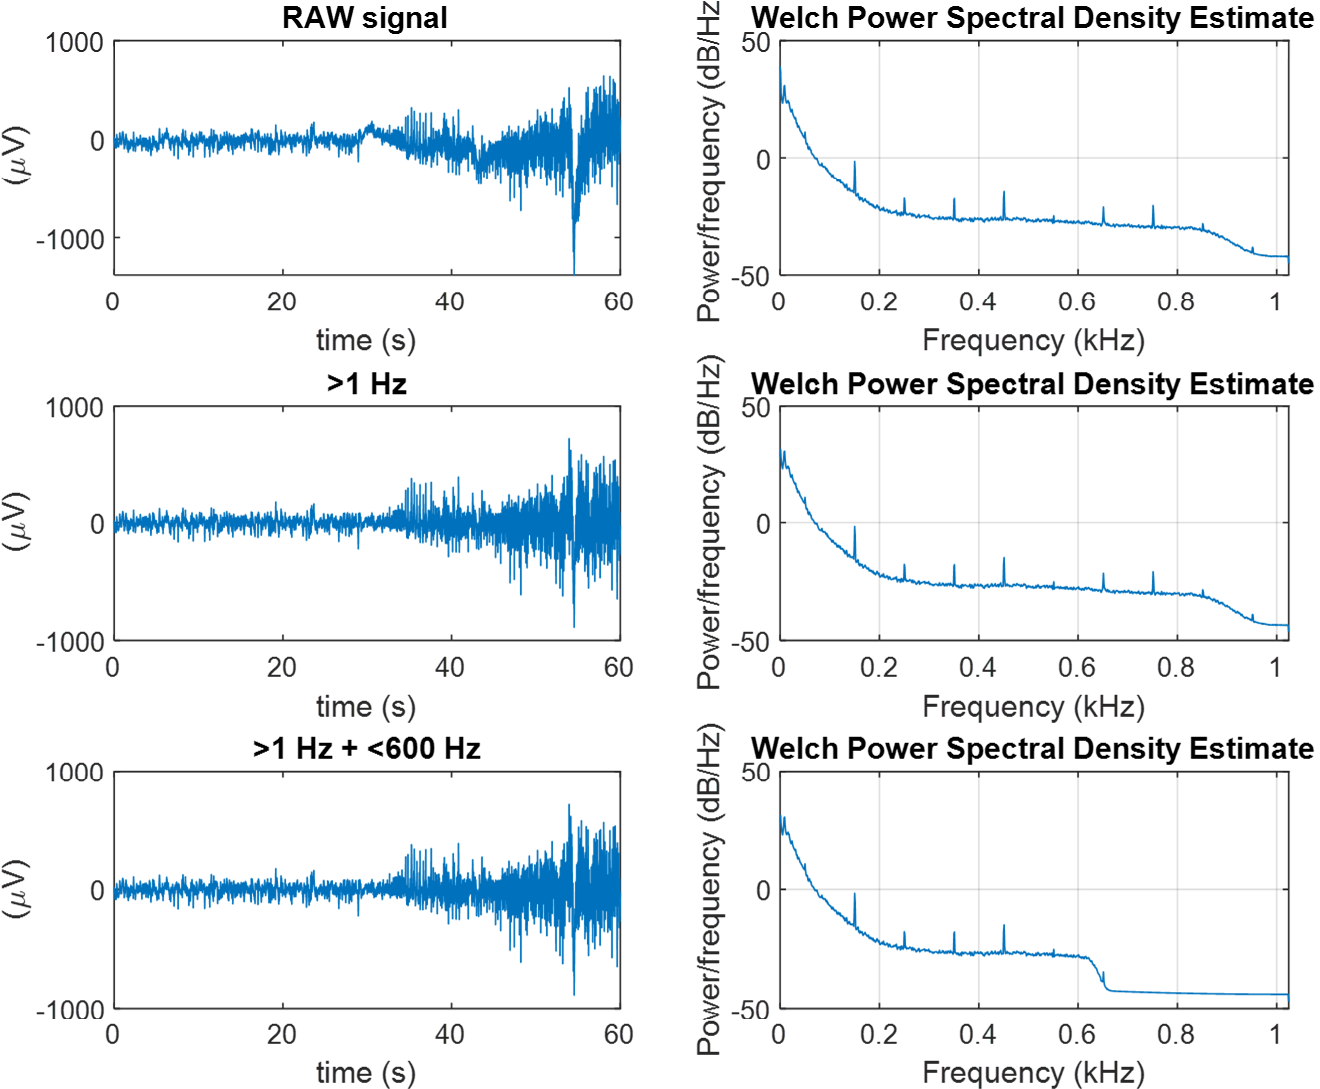

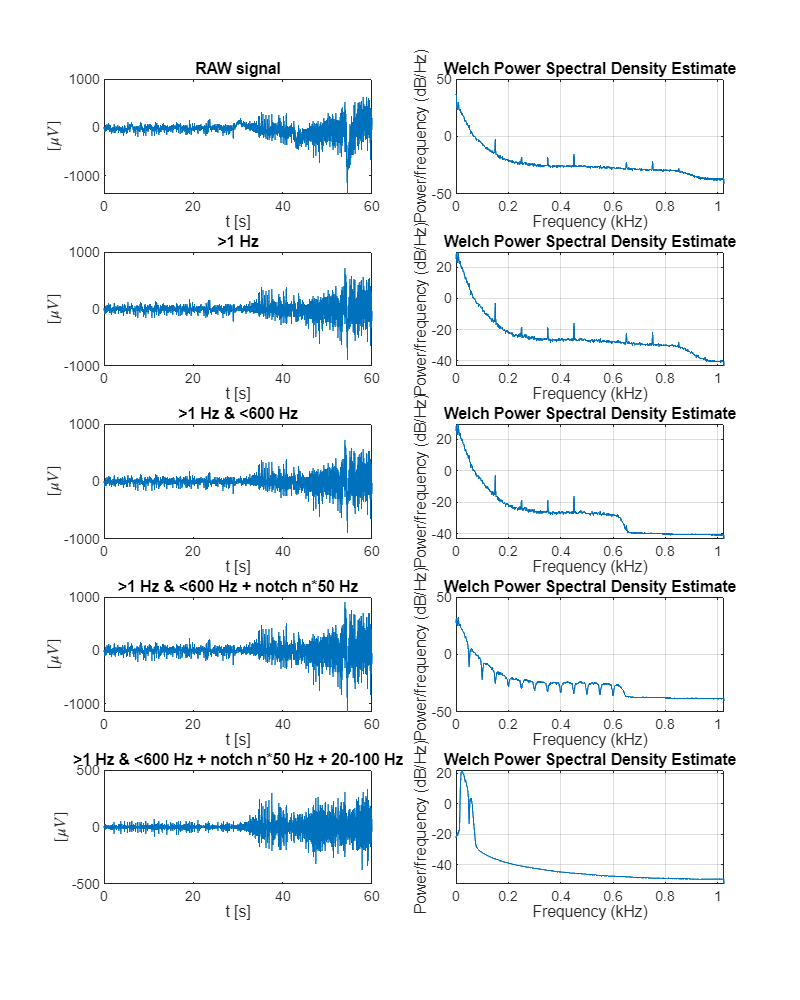

T = length(eeg)/fs;
t = linspace(0,T-1/fs,T*fs);
figure
set(gcf,'Position', [0 0 800 1000])
subplot(521) % 5x2
plot(t,eeg)
xlabel("t [s]")
ylabel('$[\mu V]$',Interpreter="latex")
title("RAW signal")
subplot(522)
pwelch(eeg,1500,50,[],fs)
x = filtfilt(bhp,ahp,eeg);
subplot(523)
plot(t,x)
xlabel("t [s]")
ylabel('$[\mu V]$',Interpreter="latex")
title(">1 Hz")
subplot(524)
pwelch(x,1500,50,[],fs)
y = filtfilt(bdp,adp,x);
subplot(525)
plot(t,y)
xlabel("t [s]")
ylabel('$[\mu V]$',Interpreter="latex")
title(">1 Hz & <600 Hz")
subplot(526)
pwelch(y,1500,50,[],fs)
% vytvořte kaskádu notch-filtrů n×50 Hz 
for f50=50:50:700 % 50, 100, 150 ... fs/2 
    R = 1;
    r = 0.99;
    w0 = 2*f50/fs;
    [b_n50,a_n50] = zp2tf([R*exp(1i*pi*w0);R*exp(-1i*pi*w0)], [r*exp(1i*pi*w0);r*exp(-1i*pi*w0)],1);        % [b50,a50]=zp2tf(...); % doplňte
    y=filtfilt(b_n50,a_n50,y); % postupně filtrujte signál          
end
subplot(527)
plot(t,y)
xlabel("t [s]")
ylabel('$[\mu V]$',Interpreter="latex")
title(">1 Hz & <600 Hz + notch n*50 Hz")
subplot(528)
pwelch(y,1500,50,[],fs)
z = filtfilt(bpp,app,y);
subplot(529)
plot(t,z)
xlabel("t [s]")
ylabel('$[\mu V]$',Interpreter="latex")
title(">1 Hz & <600 Hz + notch n*50 Hz + 20-100 Hz")
subplot(5,2,10)
pwelch(z,1500,50,[],fs)

**Ve for cyklu realizujte filtraci násobků 50 Hz pomocí notch filtrů**. Opět vykreslete filtrovaný signál i s odhadem PSD.

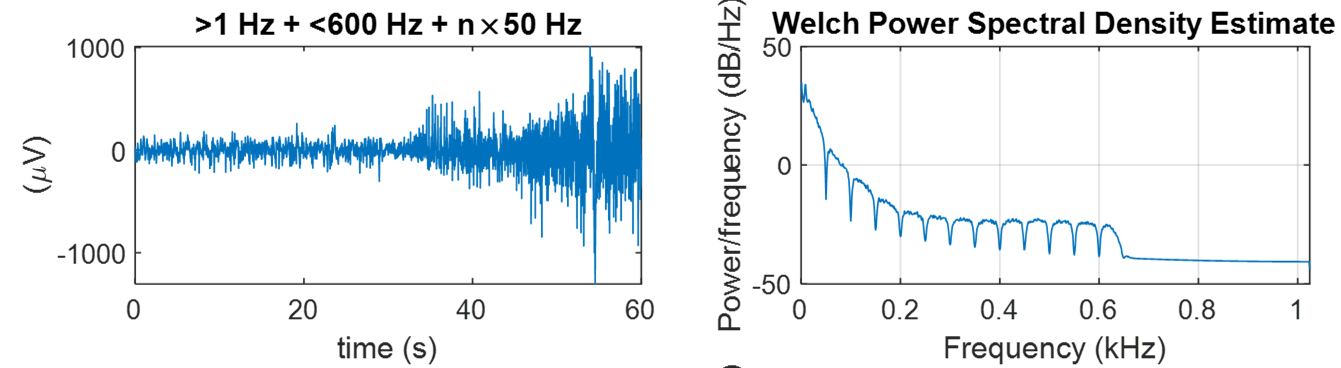

Pozn.: protože již máme signál omezen DP <600 Hz, můžeme filtraci násobků 50 Hz omezit např. na 700 Hz, kde je již útlum DP dostatečný.

R=1;
r=0.99;


**Zde získáváme vyčištěný signál od kolísání izolinie, vysokofrekvenčního rušení, síťového rušení a jeho násobků.**

Nás bude dodatečně zajímat, kdy v signálu začíná epileptický záchvat. Ten je charakterizován nárůstem gama aktivity oproti období před záchvatem. Vyfiltrujte tedy signál v pásmu 20-100 Hz.

 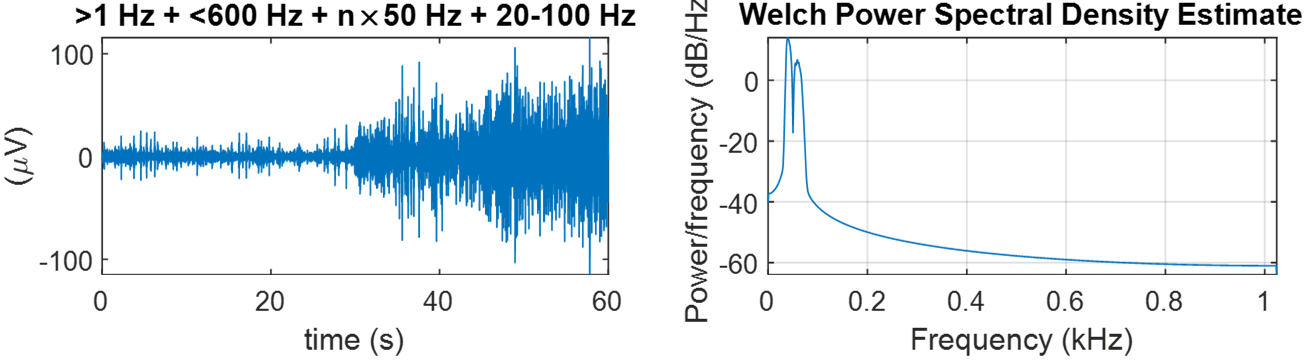 

 **Kdy podle Vás začal záchvat?** okolo 33 s

**Pozn.:** V případě, že by nás rovnou zajímala pouze aktivita v gama pásmu signálu, mohli bychom celou filtrační kaskádu nahradit jednou pásmovou propustí 20-100 Hz a jedním notch filtrem 50 Hz. 

## Bonus (+2b)

### Optimalizace cyklu filtrací Notch filtrů

V uvedené metodě filtrace úzkopásmovým Notch filtrem ve `for` cyklu generujeme v každé iteraci koeficienty ***a*** a ***b*** pro celistvé násobky 50 Hz. Následně filtrujeme funkcí `filtfilt(b,a)`, tj. proběhne filtrace, otočí se signál, filtruje se znovu a nakonec se signál otočí zpět (viz úvod / přednáška). Pro dlouhý signál s vyšším vzorkovacím kmitočtem toto může být zbytečně zdlouhavý výpočet. Protože jsou tyto filtry zapojeny kaskádně za sebou, můžeme nejprve získat kompletní koeficienty *a* a *b* za všechny tyto bloky (${\mathbf{h}}_{\textrm{Complete}} ={\mathbf{h}}_1 *{\mathbf{h}}_2 *\;\ldotp \ldotp \ldotp *\;{\mathbf{h}}_{\mathrm{K}}$) a následně filtrovat jen jednou (resp. dvakrát kvůli využití `filtfilt()`).

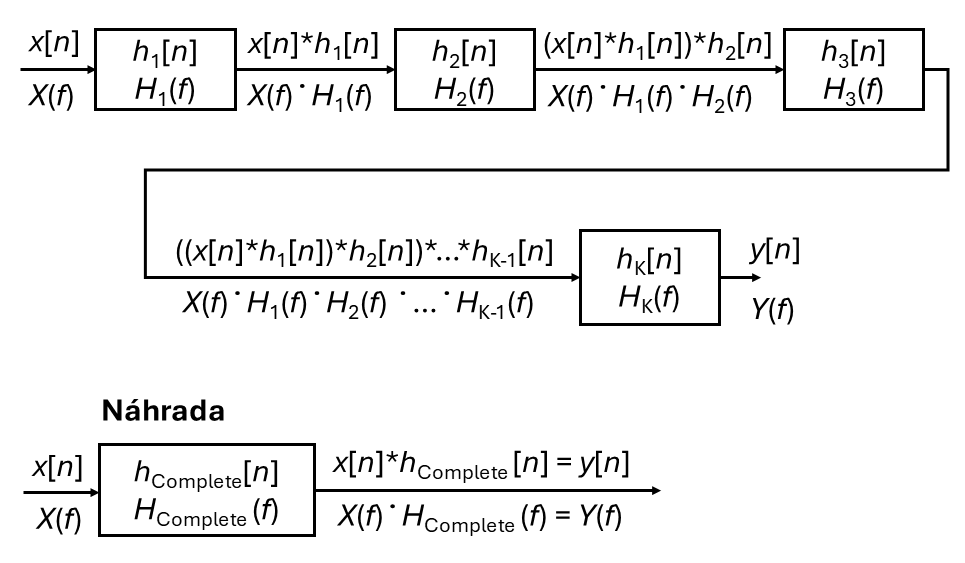

Využíváme tedy vlastností LTI systému, komutativity násobení, přepis diferenční rovnice (čas) do z-roviny, a tedy roznásobit koeficienty ***b*** mezi sebou v čitateli a koeficienty ***a ***ve jmenovateli přenosvé funkce.  

Obecně zapsáno:

$H\left(z\right)=H_1 \left(z\right)\cdot H_2 \left(z\right)\cdot \ldots\cdot H_{\mathrm{K}} \left(z\right)=\frac{b_0 \cdot z^{M_1 } +b_1 \cdot z^{M_1 -1} +\ldots+b_{M_1 } }{a_0 \cdot z^{M_1 } +a_1 \cdot z^{M_1 -1} +\ldots+a_{M_1 } }\cdot \frac{b_0 \cdot z^{M_2 } +b_1 \cdot z^{M_2 -1} +\ldots+b_{M_2 } }{a_0 \cdot z^{M_2 } +a_1 \cdot z^{M_2 -1} +\ldots+a_{M_2 } }\cdot \ldots\cdot \frac{b_0 \cdot z^{M_{\mathrm{K}} } +b_1 \cdot z^{M_{\mathrm{K}} -1} +\ldots+b_{M_{\mathrm{K}} } }{a_0 \cdot z^{M_{\mathrm{K}} } +a_1 \cdot z^{M_{\mathrm{K}} -1} +\ldots+a_{M_{\mathrm{K}} } }$,

kde $M_i$ je řád filtru $i$-tého filtru $\left(i=\left\lbrace 1,2,\ldots,K\right\rbrace \right)$. Zde máme vždy po třech koeficientech $\mathit{\mathbf{b}}=\left\lbrace b_0 ,b_1 ,b_2 \right\rbrace$a $\mathit{\mathbf{a}}=\left\lbrace a_0 ,a_1 ,a_2 \right\rbrace$. Jen nově upravené pro další násobek 50 Hz. Potom platí:


$$H\left(z\right)=H_1 \left(z\right)\cdot H_2 \left(z\right)\cdot \ldots\cdot H_{\mathrm{K}} \left(z\right)=\frac{b_{0,\;50} \cdot z^2 +b_{1,50} \cdot z+b_{2,50} }{a_{0,50} \cdot z^2 +a_{1,50} \cdot z+a_{2,50} }\cdot \frac{b_{0,100} \cdot z^2 +b_{1,100} \cdot z+b_{2,100} }{a_{0,100} \cdot z^2 +a_{1,100} \cdot z+a_{2,100} }\cdot \ldots\cdot \frac{b_{0,\;50\cdot \mathrm{K}} \cdot z^2 +b_{1,\;50\cdot \mathrm{K}} \cdot z+b_{2,\;50\cdot \mathrm{K}} }{a_{0,50\cdot \mathrm{K}} \cdot z^2 +a_{1,50\cdot \mathrm{K}} \cdot z+a_{2,\;50\cdot \mathrm{K}} }$$


**Dostáváme přenos **(příklad pro $f_s =2048$ Hz)**:**

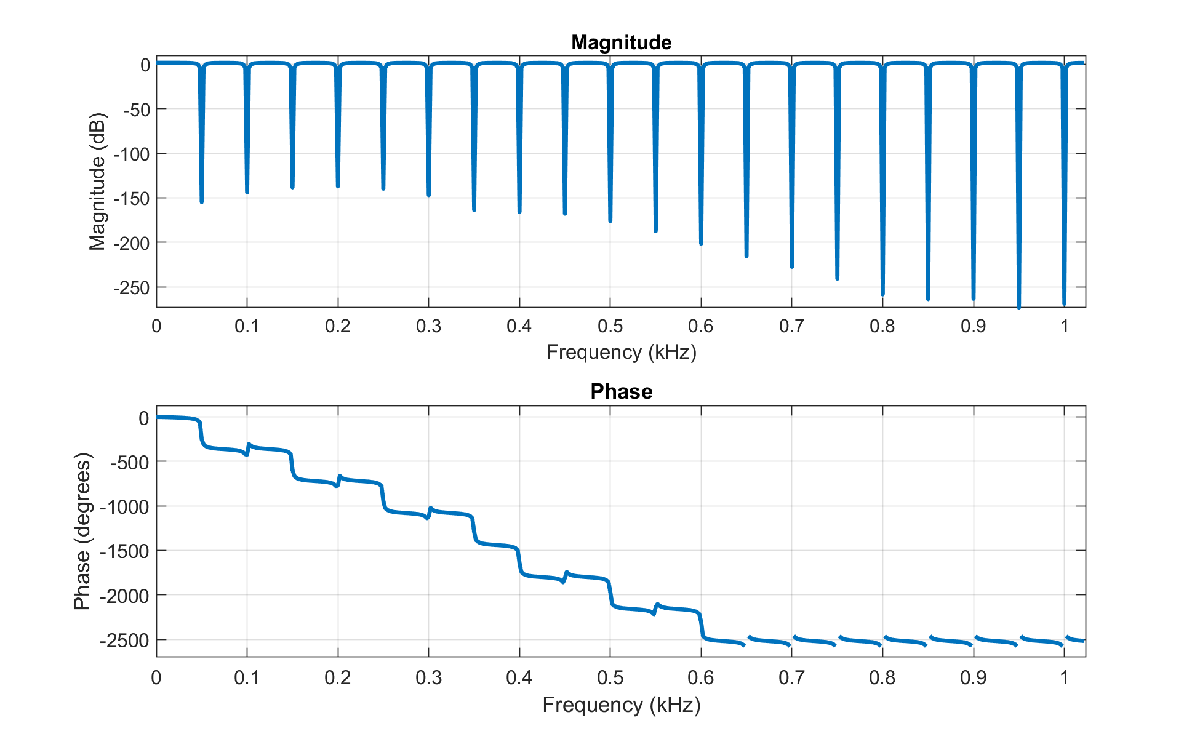

S nuly (modře) a póly (červeně):

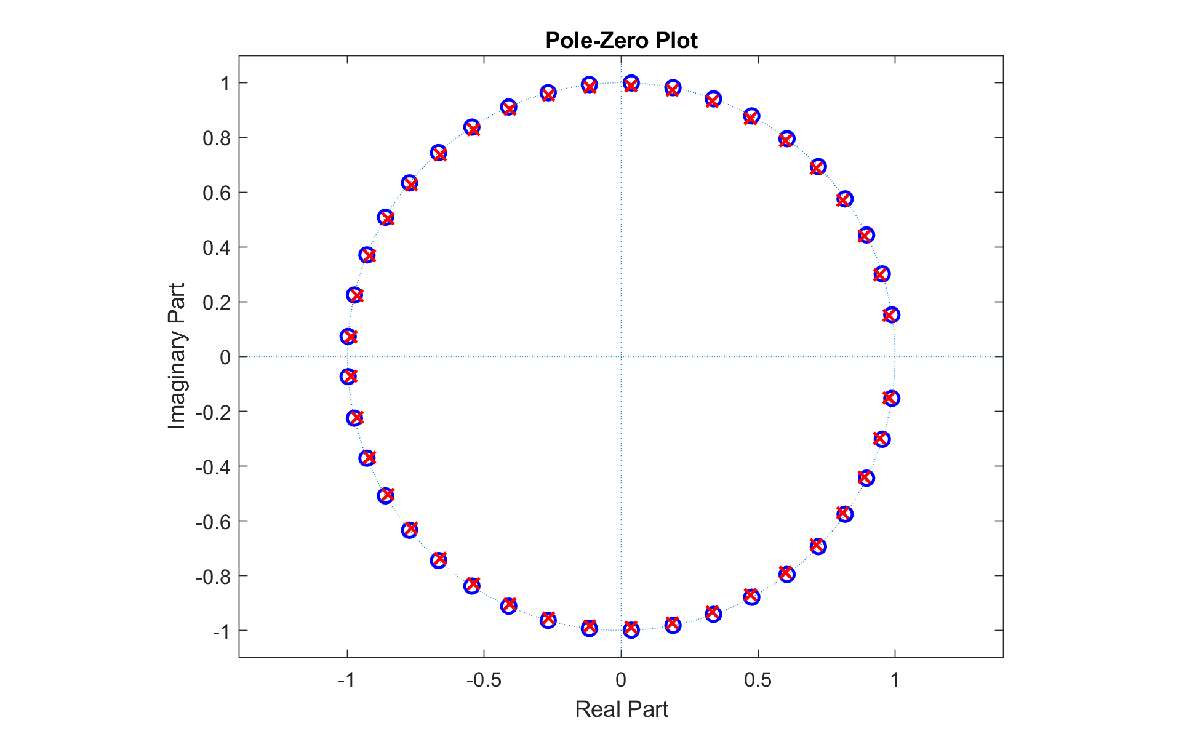

Přenosovou funkci, respektive koeficienty polynomu $b$ a $a$, můžeme získat z pozice pólů a nul a funkce `zp2tf()`:

Vytvořte si  pozice pólů a nul pro všechny násobky 50 Hz (až po fs/2) a získejte koeficienty složeného filtru.  

### Zadání

**Pro vzorkovací kmitočet **$f_s =2048$**Hz navrhněte filtr s úzkopásmovými pásmovými zádržemi na celistvých násobcích 50 Hz. Poloměry volte *****R*****=1, *****r*****=0.99. Zobrazte přenosovou charakteristiku, odezvu na jednotkový impulz, nuly a póly.**

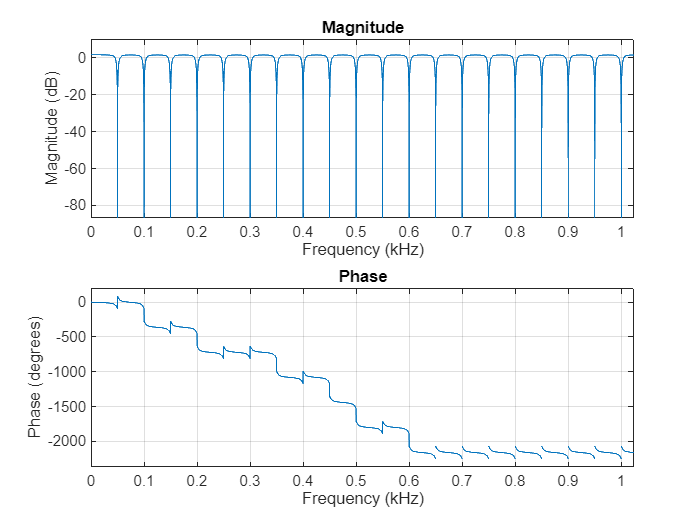

clear all;
fs = 2048;
r=0.99;
R = 1;
b = [1];
a = [1];
for f50=50:50:fs/2 % 50, 100, 150 ... fs/2 
    w0 = 2*f50/fs;
    [b_n50,a_n50]=zp2tf([R*exp(1j*pi*w0); R*exp(-1j*pi*w0)],[r*exp(1j*pi*w0); r*exp(-1j*pi*w0)],1);        
    b = conv(b, b_n50); 
    a = conv(a ,a_n50);
end

figure
freqz(b,a,100*fs,fs)

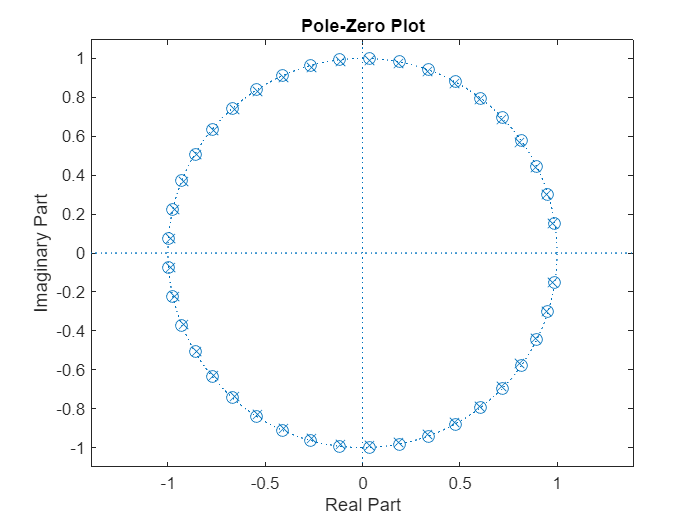

figure
zplane(b,a)

ord = length(roots(a))

ord = 40

**Odpovězte:**

**Jaký je výsledný řád filtru?**

40

**Jaký by byl řád filtr, pokud by vzorkovací kmitočet byl roven **$f_S =128$** Hz?**

2